clear
close all
clc

%% Parameters and nominal operating point
a = 1.2272*ones(4,1);
A_tank = 380.1327*ones(4,1);
gamma = [0.6;0.7];
g = 981;
rho = 1;

p = [a;A_tank;gamma;g;rho];

us = [300;300];
Fbar = [175;175];

xs = fsolve(@(x) FourTankSystem(0,x,us,Fbar,p), ...
    10000*ones(4,1),optimoptions('fsolve','Display','none'));

hs = FourTankSensors(xs,p);
zs = FourTankOutputs(xs,p);

fprintf('Nominal state x_s [g]:\n')

Nominal state x_s [g]:


disp(xs)

   1.0e+04 *

    2.5476
    3.2809
    0.9034
    1.1196



fprintf('Nominal levels h_s [cm]:\n')

Nominal levels h_s [cm]:


disp(hs)

   67.0178
   86.3084
   23.7663
   29.4520



fprintf('Nominal outputs z_s [cm]:\n')

Nominal outputs z_s [cm]:


disp(zs)

   67.0178
   86.3084




%% Continuous-time linearized models
lambda = a./A_tank.*sqrt(g./(2*hs));

A4 = [
    -lambda(1),0,lambda(3),0
    0,-lambda(2),0,lambda(4)
    0,0,-lambda(3),0
    0,0,0,-lambda(4)
];

B_u = rho*[
    gamma(1),0
    0,gamma(2)
    0,1-gamma(2)
    1-gamma(1),0
];

B_d = rho*[
    0,0
    0,0
    1,0
    0,1
];

% Levels of all four tanks
C_h = diag(1./(rho*A_tank));

% Measured outputs: only tank 1 and tank 2
C_y = C_h(1:2,:);

% Controlled outputs: tank 1 and tank 2
C_z = C_y;

C_y_PWC = C_y;
D_y_PWC = zeros(2,2);

C_y_Brownian = [C_y zeros(2,2)];
D_y_Brownian = zeros(2,2);

C_y_OU = [C_y zeros(2,2)];
D_y_OU = zeros(2,2);

%% PWC model
A_PWC = A4;
B_PWC = B_u;
E_PWC = B_d;
C_PWC = C_z;
D_PWC = zeros(2);
F_PWC = zeros(2);

% Compatibility names for later sections
B_u_PWC = B_u;
B_d_PWC = B_d;

%% Brownian model
Ts = 4;
sigma_B = 17.5/sqrt(Ts);

A_Brownian = [
    A4,B_d
    zeros(2,4),zeros(2)
];

B_u_Brownian = [
    B_u
    zeros(2,2)
];

C_Brownian = [C_z,zeros(2,2)];
D_Brownian = zeros(2);

G_Brownian = [
    zeros(4,2)
    sigma_B*eye(2)
];

%% Ornstein-Uhlenbeck model
tau_F = 40;
a_F = 1/tau_F;
sigma_F = 17.5;
sigma_OU = sigma_F*sqrt(2*a_F);

A_OU = [
    A4,B_d
    zeros(2,4),-a_F*eye(2)
];

B_u_OU = [
    B_u
    zeros(2,2)
];

C_OU = [C_z,zeros(2,2)];
D_OU = zeros(2);

G_OU = [
    zeros(4,2)
    sigma_OU*eye(2)
];

%% Display main matrices
fprintf('\nPWC model\n')


PWC model


disp(A_PWC)

   -0.0087         0    0.0147         0
         0   -0.0077         0    0.0132
         0         0   -0.0147         0
         0         0         0   -0.0132



disp(B_PWC)

    0.6000         0
         0    0.7000
         0    0.3000
    0.4000         0



disp(E_PWC)

     0     0
     0     0
     1     0
     0     1



disp(C_PWC)

    0.0026         0         0         0
         0    0.0026         0         0



fprintf('\nBrownian model\n')


Brownian model


disp(A_Brownian)

   -0.0087         0    0.0147         0         0         0
         0   -0.0077         0    0.0132         0         0
         0         0   -0.0147         0    1.0000         0
         0         0         0   -0.0132         0    1.0000
         0         0         0         0         0         0
         0         0         0         0         0         0



disp(B_u_Brownian)

    0.6000         0
         0    0.7000
         0    0.3000
    0.4000         0
         0         0
         0         0



disp(C_Brownian)

    0.0026         0         0         0         0         0
         0    0.0026         0         0         0         0



disp(G_Brownian)

         0         0
         0         0
         0         0
         0         0
    8.7500         0
         0    8.7500



fprintf('\nOU model\n')


OU model


disp(A_OU)

   -0.0087         0    0.0147         0         0         0
         0   -0.0077         0    0.0132         0         0
         0         0   -0.0147         0    1.0000         0
         0         0         0   -0.0132         0    1.0000
         0         0         0         0   -0.0250         0
         0         0         0         0         0   -0.0250



disp(B_u_OU)

    0.6000         0
         0    0.7000
         0    0.3000
    0.4000         0
         0         0
         0         0



disp(C_OU)

    0.0026         0         0         0         0         0
         0    0.0026         0         0         0         0



disp(G_OU)

         0         0
         0         0
         0         0
         0         0
    3.9131         0
         0    3.9131



%% 5.2 Continuous-time transfer functions

%% PWC model
sys_c_PWC_u = ss(A_PWC,B_PWC,C_PWC,D_PWC);
G_c_PWC_u = tf(sys_c_PWC_u);
sys_c_PWC_d = ss(A_PWC,E_PWC,C_PWC,F_PWC);
G_c_PWC_d = tf(sys_c_PWC_d);

%% Brownian model
sys_c_Brownian_u = ss(A_Brownian,B_u_Brownian,C_Brownian,D_Brownian);

G_c_Brownian_u = tf(sys_c_Brownian_u);

sys_c_Brownian_w = ss(A_Brownian,G_Brownian,C_Brownian,zeros(2));

G_c_Brownian_w = tf(sys_c_Brownian_w);

%% Ornstein-Uhlenbeck model
sys_c_OU_u = ss(A_OU,B_u_OU,C_OU,D_OU);

G_c_OU_u = tf(sys_c_OU_u);

sys_c_OU_w = ss(A_OU,G_OU,C_OU,zeros(2));

G_c_OU_w = tf(sys_c_OU_w);

%% Display manipulated-input transfer functions

fprintf('\nPWC model: u -> z\n')


PWC model: u -> z


G_c_PWC_u


G_c_PWC_u =
 
  From input 1 to output...
         0.001578
   1:  ------------
       s + 0.008734
 
                1.386e-05
   2:  ---------------------------
       s^2 + 0.02087 s + 0.0001014
 
  From input 2 to output...
               1.157e-05
   1:  --------------------------
       s^2 + 0.0234 s + 0.0001281
 
         0.001841
   2:  ------------
       s + 0.007696
 
Continuous-time transfer function.



fprintf('\nBrownian model: u -> z\n')


Brownian model: u -> z


G_c_Brownian_u


G_c_Brownian_u =
 
  From input 1 to output...
         0.001578
   1:  ------------
       s + 0.008734
 
                1.386e-05
   2:  ---------------------------
       s^2 + 0.02087 s + 0.0001014
 
  From input 2 to output...
               1.157e-05
   1:  --------------------------
       s^2 + 0.0234 s + 0.0001281
 
         0.001841
   2:  ------------
       s + 0.007696
 
Continuous-time transfer function.



fprintf('\nOU model: u -> z\n')


OU model: u -> z


G_c_OU_u


G_c_OU_u =
 
  From input 1 to output...
         0.001578
   1:  ------------
       s + 0.008734
 
                1.386e-05
   2:  ---------------------------
       s^2 + 0.02087 s + 0.0001014
 
  From input 2 to output...
               1.157e-05
   1:  --------------------------
       s^2 + 0.0234 s + 0.0001281
 
         0.001841
   2:  ------------
       s + 0.007696
 
Continuous-time transfer function.



%% Compare manipulated-input transfer functions
for i = 1:2
    for j = 1:2
        errorBrownian = norm(G_c_PWC_u(i,j)-G_c_Brownian_u(i,j));
        errorOU = norm(G_c_PWC_u(i,j)-G_c_OU_u(i,j));
        fprintf( ...
            'G%d%d: PWC-Brownian = %.3e, PWC-OU = %.3e\n', ...
            i,j,errorBrownian,errorOU);
    end
end

G11: PWC-Brownian = 0.000e+00, PWC-OU = 0.000e+00
G12: PWC-Brownian = 0.000e+00, PWC-OU = 0.000e+00
G21: PWC-Brownian = 0.000e+00, PWC-OU = 0.000e+00
G22: PWC-Brownian = 0.000e+00, PWC-OU = 0.000e+00



fprintf('\nPWC disturbance transfer functions:\n')


PWC disturbance transfer functions:


G_c_PWC_d


G_c_PWC_d =
 
  From input 1 to output...
               3.858e-05
   1:  --------------------------
       s^2 + 0.0234 s + 0.0001281
 
   2:  0
 
  From input 2 to output...
   1:  0
 
                3.466e-05
   2:  ---------------------------
       s^2 + 0.02087 s + 0.0001014
 
Continuous-time transfer function.



fprintf('\nBrownian noise transfer functions:\n')


Brownian noise transfer functions:


G_c_Brownian_w


G_c_Brownian_w =
 
  From input 1 to output...
                 0.0003376
   1:  ------------------------------
       s^3 + 0.0234 s^2 + 0.0001281 s
 
   2:  0
 
  From input 2 to output...
   1:  0
 
                  0.0003033
   2:  -------------------------------
       s^3 + 0.02087 s^2 + 0.0001014 s
 
Continuous-time transfer function.



fprintf('\nOU noise transfer functions:\n')


OU noise transfer functions:


G_c_OU_w


G_c_OU_w =
 
  From input 1 to output...
                        0.000151
   1:  ------------------------------------------
       s^3 + 0.0484 s^2 + 0.0007131 s + 3.202e-06
 
   2:  0
 
  From input 2 to output...
   1:  0
 
                        0.0001356
   2:  -------------------------------------------
       s^3 + 0.04587 s^2 + 0.0006232 s + 2.535e-06
 
Continuous-time transfer function.


%% 5.3 Comparison with Problem 4

filename = 'TF_Parameters.xlsx';
Table_Deterministic = readtable(filename,'Sheet','Deterministic 1st Order');
Table_Stochastic = readtable(filename,'Sheet','Stochastic 1st Order');

transferFunctionNames = ["G11";"G12";"G21";"G22"];

G_linearized = {
    G_c_PWC_u
    G_c_Brownian_u
    G_c_OU_u
};

modelNames = ["PWC";"Brownian";"OU"];

nModels = numel(G_linearized);
nTF = numel(transferFunctionNames);

Gain_CT = zeros(nModels,nTF);
Tau_CT = zeros(nModels,nTF);

%% Linearized gains and time constants
for m = 1:nModels

    for i = 1:2
        for j = 1:2

            k = 2*(i-1)+j;
            Gij = minreal(G_linearized{m}(i,j));

            Gain_CT(m,k) = dcgain(Gij);

            stablePoles = pole(Gij);
            stablePoles = stablePoles(real(stablePoles) < -1e-9);

            if isempty(stablePoles)
                Tau_CT(m,k) = NaN;
            else
                Tau_CT(m,k) = max(-1./real(stablePoles));
            end
        end
    end
end

%% Export linearized results
LinearizedTable = table( ...
    repelem(modelNames,nTF), ...
    repmat(transferFunctionNames,nModels,1), ...
    reshape(Gain_CT.',[],1), ...
    reshape(Tau_CT.',[],1), ...
    'VariableNames', ...
    {'Model','TransferFunction','Gain_CT','DominantTau_s'});
disp('Linearized continuous-time parameters:')

Linearized continuous-time parameters:


disp(LinearizedTable)

      Model       TransferFunction    Gain_CT     DominantTau_s
    __________    ________________    ________    _____________

    "PWC"              "G11"           0.18072        114.5    
    "PWC"              "G12"          0.090361        114.5    
    "PWC"              "G21"           0.13673       129.94    
    "PWC"              "G22"           0.23927       129.94    
    "Brownian"         "G11"           0.18072        114.5    
    "Brownian"         "G12"          0.090361        114.5    
    "Brownian"         "G21"           0.13673       129.94    
    "Brownian"         "G22"           0.23927       129.94    
    "OU"               "G11"           0.18072        114.5    
    "OU"               "G12"          0.090361        114.5    
    "OU"               "G21"           0.13673       129.94    
    "OU"               "G22"   

writetable(LinearizedTable,filename,'Sheet','P5 Linearized CT');

%% Read Problem 4 parameters
Gain_Deterministic = zeros(nTF,1);
Tau_Deterministic = zeros(nTF,1);
Gain_Stochastic = zeros(nTF,1);
Tau_Stochastic = zeros(nTF,1);

for k = 1:nTF
    name = transferFunctionNames(k);
    idxDet = find(string(Table_Deterministic.TransferFunction) == name,1);
    idxSto = find(string(Table_Stochastic.TransferFunction) == name,1);

    if isempty(idxDet) || isempty(idxSto)
        error('Transfer function %s was not found in TF_Parameters.xlsx.',name)
    end
    Gain_Deterministic(k) = Table_Deterministic.Gain(idxDet);
    Tau_Deterministic(k) = Table_Deterministic.Tau_s(idxDet);
    Gain_Stochastic(k) = Table_Stochastic.Gain(idxSto);
    Tau_Stochastic(k) = Table_Stochastic.Tau_s(idxSto);
end

%% Comparison table
Gain_Linearized = Gain_CT(1,:)';
Tau_Linearized = Tau_CT(1,:)';

%% Comparison table
Gain_Linearized = Gain_CT(1,:)';
Tau_Linearized = Tau_CT(1,:)';
GainError_Deterministic =Gain_Linearized - Gain_Deterministic;
TauError_Deterministic =Tau_Linearized - Tau_Deterministic;
GainError_Stochastic =Gain_Linearized - Gain_Stochastic;
TauError_Stochastic =Tau_Linearized - Tau_Stochastic;
GainRelativeError_Deterministic =100*abs(GainError_Deterministic) ./ abs(Gain_Deterministic);
TauRelativeError_Deterministic =100*abs(TauError_Deterministic) ./ abs(Tau_Deterministic);
GainRelativeError_Stochastic =100*abs(GainError_Stochastic) ./ abs(Gain_Stochastic);
TauRelativeError_Stochastic =100*abs(TauError_Stochastic) ./ abs(Tau_Stochastic);
ComparisonTable = table( ...
    transferFunctionNames, ...
    Gain_Linearized, ...
    Tau_Linearized, ...
    Gain_Deterministic, ...
    Tau_Deterministic, ...
    GainError_Deterministic, ...
    GainRelativeError_Deterministic, ...
    TauError_Deterministic, ...
    TauRelativeError_Deterministic, ...
    Gain_Stochastic, ...
    Tau_Stochastic, ...
    GainError_Stochastic, ...
    GainRelativeError_Stochastic, ...
    TauError_Stochastic, ...
    TauRelativeError_Stochastic, ...
    'VariableNames', ...
    {'TransferFunction', ...
    'Gain_Linearized', ...
    'Tau_Linearized_s', ...
    'Gain_Problem4_Deterministic', ...
    'Tau_Problem4_Deterministic_s', ...
    'GainError_Deterministic', ...
    'GainRelativeError_Deterministic_percent', ...
    'TauError_Deterministic_s', ...
    'TauRelativeError_Deterministic_percent', ...
    'Gain_Problem4_Stochastic', ...
    'Tau_Problem4_Stochastic_s', ...
    'GainError_Stochastic', ...
    'GainRelativeError_Stochastic_percent', ...
    'TauError_Stochastic_s', ...
    'TauRelativeError_Stochastic_percent'});

disp('Comparison with Problem 4:')

Comparison with Problem 4:


disp(ComparisonTable)

    TransferFunction    Gain_Linearized    Tau_Linearized_s    Gain_Problem4_Deterministic    Tau_Problem4_Deterministic_s    GainError_Deterministic    GainRelativeError_Deterministic_percent    TauError_Deterministic_s    TauRelativeError_Deterministic_percent    Gain_Problem4_Stochastic    Tau_Problem4_Stochastic_s    GainError_Stochastic    GainRelativeError_Stochastic_percent    TauError_Stochastic_s    TauRelativeError_Stochastic_percent
    ________________    _______________    ________________    ___________________________    ____________________________    _______________________    __________________________________

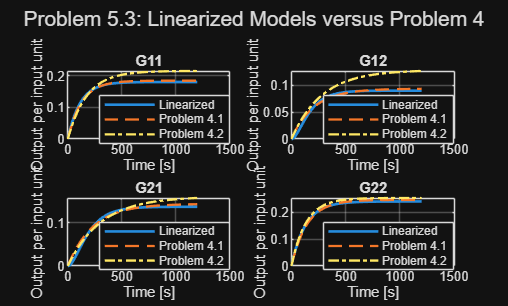

writetable(ComparisonTable,filename,'Sheet','P5 Comparison');

%% Plot comparison
timePlot = (0:1:1200)';
figure

for i = 1:2
    for j = 1:2

        k = 2*(i-1)+j;
        subplot(2,2,k)
        [yLinearized,~] = step(G_c_PWC_u(i,j),timePlot);
        plot(timePlot,squeeze(yLinearized),'LineWidth',1.6,'DisplayName','Linearized')
        hold on
        GDet = tf(Gain_Deterministic(k),[Tau_Deterministic(k) 1]);
        GSto = tf(Gain_Stochastic(k),[Tau_Stochastic(k) 1]);
        [yDet,~] = step(GDet,timePlot);
        [ySto,~] = step(GSto,timePlot);
        plot(timePlot,squeeze(yDet),'--', ...
            'LineWidth',1.4,'DisplayName','Problem 4.1')
        plot(timePlot,squeeze(ySto),'-.', ...
            'LineWidth',1.4,'DisplayName','Problem 4.2')
        grid on
        xlabel('Time [s]')
        ylabel('Output per input unit')
        title(transferFunctionNames(k))
        legend('Location','best')

    end
end

sgtitle('Problem 5.3: Linearized Models versus Problem 4')

%% 5.4 Discrete-time state-space models

Ts_disc = 4;

%% PWC model

sys_d_PWC_u = c2d(sys_c_PWC_u,Ts_disc,'zoh');
[A_d_PWC,B_d_PWC,C_d_PWC,D_d_PWC] = ssdata(sys_d_PWC_u);

sys_d_PWC_d = c2d(sys_c_PWC_d,Ts_disc,'zoh');
[~,E_d_PWC,~,F_d_PWC] = ssdata(sys_d_PWC_d);

%% Brownian model

sys_d_Brownian_u = c2d(sys_c_Brownian_u,Ts_disc,'zoh');

[A_d_Brownian,B_d_Brownian,C_d_Brownian,D_d_Brownian] =ssdata(sys_d_Brownian_u);

% Exact discrete-time covariance for Brownian process noise
nB = size(A_Brownian,1);

VB = expm([-A_Brownian, G_Brownian*G_Brownian';zeros(nB), A_Brownian'] * Ts_disc);

PhiB = VB(nB+1:end,nB+1:end)';
Q_d_Brownian = PhiB * VB(1:nB,nB+1:end);

Q_d_Brownian = (Q_d_Brownian + Q_d_Brownian')/2;


%% Ornstein-Uhlenbeck model

sys_d_OU_u = c2d(sys_c_OU_u,Ts_disc,'zoh');

[A_d_OU,B_d_OU,C_d_OU,D_d_OU] =ssdata(sys_d_OU_u);

% Exact discrete-time covariance for OU process noise
nOU = size(A_OU,1);
VOU = expm([-A_OU, G_OU*G_OU';zeros(nOU), A_OU'] * Ts_disc);
PhiOU = VOU(nOU+1:end,nOU+1:end)';
Q_d_OU = PhiOU * VOU(1:nOU,nOU+1:end);

Q_d_OU =(Q_d_OU + Q_d_OU')/2;

%% Display discrete-time matrices

modelNames_d = {
    'PWC'
    'Brownian'
    'OU'
    };

A_d_models = {
    A_d_PWC
    A_d_Brownian
    A_d_OU
    };

B_d_models = {
    B_d_PWC
    B_d_Brownian
    B_d_OU
    };

C_d_models = {
    C_d_PWC
    C_d_Brownian
    C_d_OU
    };

D_d_models = {
    D_d_PWC
    D_d_Brownian
    D_d_OU
    };

Q_d_PWC = zeros(size(A_d_PWC));

Q_d_models = {
    Q_d_PWC
    Q_d_Brownian
    Q_d_OU
    };

for k = 1:3
    fprintf('\n================ %s MODEL ================\n', ...
        upper(modelNames{k}));
    disp('A_d =')
    disp(A_d_models{k})
    disp('B_d =')
    disp(B_d_models{k})
    disp('C_d =')
    disp(C_d_models{k})
    disp('D_d =')
    disp(D_d_models{k})
    disp('Q_d =')
    disp(Q_d_models{k})
    fprintf('Dimensions: A = %d x %d, B = %d x %d\n', ...
        size(A_d_models{k},1),size(A_d_models{k},2), ...
        size(B_d_models{k},1),size(B_d_models{k},2));
    fprintf('Eigenvalues of A_d:\n')
    disp(eig(A_d_models{k}))

end


================ PWC MODEL ================


A_d =


    0.9657         0    0.0560         0
         0    0.9697         0    0.0505
         0         0    0.9430         0
         0         0         0    0.9487



B_d =


    2.3586    0.0341
    0.0410    2.7573
         0    1.1655
    1.5586         0



C_d =


    0.0026         0         0         0
         0    0.0026         0         0



D_d =


     0     0
     0     0



Q_d =


     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0



Dimensions: A = 4 x 4, B = 4 x 2


Eigenvalues of A_d:


    0.9657
    0.9697
    0.9430
    0.9487




================ BROWNIAN MODEL ================


A_d =


    0.9657         0    0.0560         0    0.1137         0
         0    0.9697         0    0.0505         0    0.1025
         0         0    0.9430         0    3.8849         0
         0         0         0    0.9487         0    3.8964
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000



B_d =


    2.3586    0.0341
    0.0410    2.7573
         0    1.1655
    1.5586         0
         0         0
         0         0



C_d =


    0.0026         0         0         0         0         0
         0    0.0026         0         0         0         0



D_d =


     0     0
     0     0



Q_d =


   1.0e+03 *

    0.0008         0    0.0342         0    0.0117         0
         0    0.0006         0    0.0309         0    0.0105
    0.0342         0    1.5634         0    0.6007         0
         0    0.0309         0    1.5703         0    0.6019
    0.0117         0    0.6007         0    0.3063         0
         0    0.0105         0    0.6019         0    0.3063



Dimensions: A = 6 x 6, B = 6 x 2


Eigenvalues of A_d:


    0.9657
    0.9697
    0.9430
    0.9487
    1.0000
    1.0000




================ OU MODEL ================


A_d =


    0.9657         0    0.0560         0    0.1100         0
         0    0.9697         0    0.0505         0    0.0992
         0         0    0.9430         0    3.6952         0
         0         0         0    0.9487         0    3.7063
         0         0         0         0    0.9048         0
         0         0         0         0         0    0.9048



B_d =


    2.3586    0.0341
    0.0410    2.7573
         0    1.1655
    1.5586         0
         0         0
         0         0



C_d =


    0.0026         0         0         0         0         0
         0    0.0026         0         0         0         0



D_d =


     0     0
     0     0



Q_d =


    0.1515         0    6.4076         0    2.1186         0
         0    0.1229         0    5.7853         0    1.9079
    6.4076         0  290.1802         0  108.7978         0
         0    5.7853         0  291.4788         0  109.0123
    2.1186         0  108.7978         0   55.5137         0
         0    1.9079         0  109.0123         0   55.5137



Dimensions: A = 6 x 6, B = 6 x 2


Eigenvalues of A_d:


    0.9657
    0.9697
    0.9430
    0.9487
    0.9048
    0.9048



%% 5.5 Markov parameters

N_markov = 300;

A_models = {
    A_d_PWC
    A_d_Brownian
    A_d_OU
};

B_models = {
    B_d_PWC
    B_d_Brownian
    B_d_OU
};

C_models = {
    C_d_PWC
    C_d_Brownian
    C_d_OU
};

D_models = {
    D_d_PWC
    D_d_Brownian
    D_d_OU};

H_models = cell(3,1);

for m = 1:3

    H_models{m} = zeros(2,2,N_markov+1);
    H_models{m}(:,:,1) = D_models{m};

    for k = 1:N_markov
        H_models{m}(:,:,k+1) =C_models{m} * ...
            A_models{m}^(k-1) * B_models{m};
    end
end

H_PWC = H_models{1};
H_Brownian = H_models{2};
H_OU = H_models{3};

%% Load Markov parameters from Problem 4

if ~isfile('Markov_Hankel.mat') ||~isfile('Markov_Hankel_stochastic.mat')
    error(['Run Problem_41.m and Problem_42.m first. ','The Markov parameter files were not found.'])
end

Problem4_Deterministic = load('Markov_Hankel.mat');
Problem4_Stochastic = load('Markov_Hankel_stochastic.mat');

H_Problem4_Deterministic = Problem4_Deterministic.H;
tH_Problem4_Deterministic = Problem4_Deterministic.tH;

H_Problem4_Stochastic = Problem4_Stochastic.H_stochastic;
tH_Problem4_Stochastic = Problem4_Stochastic.tH_stochastic;

%% Compare the three linearized models

error_Brownian = max(abs(H_PWC(:)-H_Brownian(:)));
error_OU = max(abs(H_PWC(:)-H_OU(:)));

fprintf('\nPWC-Brownian maximum error: %.3e\n',error_Brownian)


PWC-Brownian maximum error: 8.674e-19


fprintf('PWC-OU maximum error: %.3e\n',error_OU)

PWC-OU maximum error: 8.674e-19


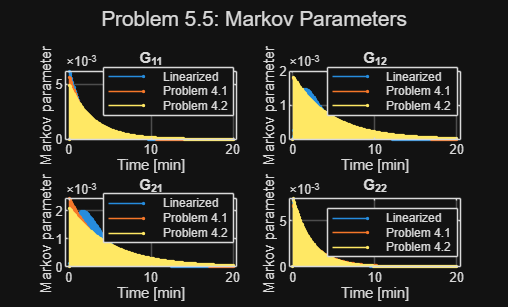


%% Plot Markov parameters

figure

for i = 1:2
    for j = 1:2

        k = 2*(i-1)+j;
        subplot(2,2,k)
        stem((0:N_markov)*Ts_disc/60,squeeze(H_PWC(i,j,:)),'.','DisplayName','Linearized')
        hold on
        stem(tH_Problem4_Deterministic/60,squeeze(H_Problem4_Deterministic(i,j,:)),'.', 'DisplayName','Problem 4.1')
        stem(tH_Problem4_Stochastic/60,squeeze(H_Problem4_Stochastic(i,j,:)),'.','DisplayName','Problem 4.2')
        grid on
        xlabel('Time [min]')
        ylabel('Markov parameter')
        title(sprintf('G_{%d%d}',i,j))
        legend('Location','best')

    end
end

sgtitle('Problem 5.5: Markov Parameters')


%% Export Markov comparison to Excel

nSamples = min([size(H_PWC,3), ...
    size(H_Problem4_Deterministic,3),size(H_Problem4_Stochastic,3)]);

nRows = 4*nSamples;

TransferFunctionColumn = strings(nRows,1);
SampleColumn = zeros(nRows,1);
TimeColumn = zeros(nRows,1);

LinearizedColumn = zeros(nRows,1);
DeterministicColumn = zeros(nRows,1);
StochasticColumn = zeros(nRows,1);

ErrorDeterministicColumn = zeros(nRows,1);
ErrorStochasticColumn = zeros(nRows,1);

row = 0;

for i = 1:2
    for j = 1:2
        for k = 1:nSamples

            row = row+1;

            TransferFunctionColumn(row) =string(sprintf('G%d%d',i,j));

            SampleColumn(row) = k-1;
            TimeColumn(row) = (k-1)*Ts_disc;

            LinearizedColumn(row) = H_PWC(i,j,k);
            DeterministicColumn(row) =H_Problem4_Deterministic(i,j,k);
            StochasticColumn(row) =H_Problem4_Stochastic(i,j,k);
            ErrorDeterministicColumn(row) =LinearizedColumn(row)-DeterministicColumn(row);
            ErrorStochasticColumn(row) = LinearizedColumn(row)-StochasticColumn(row);

        end
    end
end

MarkovComparisonTable = table( ...
    TransferFunctionColumn, ...
    SampleColumn, ...
    TimeColumn, ...
    LinearizedColumn, ...
    DeterministicColumn, ...
    StochasticColumn, ...
    ErrorDeterministicColumn, ...
    ErrorStochasticColumn, ...
    'VariableNames', ...
    {'TransferFunction','Sample','Time_s', ...
    'Linearized','Problem4_Deterministic', ...
    'Problem4_Stochastic','Error_Deterministic', ...
    'Error_Stochastic'});

writetable(MarkovComparisonTable,'TF_Parameters.xlsx','Sheet','P5 Markov Comparison');

%% 5.6 Summary of Markov parameter comparison

transferFunctions = ["G11";"G12";"G21";"G22"];

H_problem4 = {H_Problem4_Deterministic;H_Problem4_Stochastic};

nTF = numel(transferFunctions);

H1 = zeros(nTF,3);
MaxError = zeros(nTF,2);
RMSError = zeros(nTF,2);
RelativeError = zeros(nTF,2);

for i = 1:2
    for j = 1:2

        row = 2*(i-1)+j;
        hLinearized = squeeze(H_PWC(i,j,1:nSamples));
        H1(row,1) = hLinearized(2);

        for m = 1:2

            hProblem4 = squeeze(H_problem4{m}(i,j,1:nSamples));
            errorMarkov = hLinearized-hProblem4;
            H1(row,m+1) = hProblem4(2);
            MaxError(row,m) = max(abs(errorMarkov));
            RMSError(row,m) = sqrt(mean(errorMarkov.^2));
            RelativeError(row,m) = norm(errorMarkov)/norm(hProblem4);

        end
    end
end

MarkovSummaryTable = table( ...
    transferFunctions, ...
    H1(:,1), ...
    H1(:,2), ...
    H1(:,3), ...
    MaxError(:,1), ...
    MaxError(:,2), ...
    RMSError(:,1), ...
    RMSError(:,2), ...
    RelativeError(:,1), ...
    RelativeError(:,2), ...
    'VariableNames', ...
    {'TransferFunction', ...
    'H1_Linearized', ...
    'H1_Problem4_Deterministic', ...
    'H1_Problem4_Stochastic', ...
    'MaxError_Deterministic', ...
    'MaxError_Stochastic', ...
    'RMSError_Deterministic', ...
    'RMSError_Stochastic', ...
    'RelativeError_Deterministic', ...
    'RelativeError_Stochastic'});

disp('Markov parameter summary:')

Markov parameter summary:


disp(MarkovSummaryTable)

    TransferFunction    H1_Linearized    H1_Problem4_Deterministic    H1_Problem4_Stochastic    MaxError_Deterministic    MaxError_Stochastic    RMSError_Deterministic    RMSError_Stochastic    RelativeError_Deterministic    RelativeError_Stochastic
    ________________    _____________    _________________________    ______________________    ______________________    ___________________    ______________________    ___________________    ___________________________    ________________________

         "G11"            0.0062046               0.005674                  0.0048826                 0.00053061                0.001322               9.0098e-


writetable(MarkovSummaryTable,'TF_Parameters.xlsx','Sheet','P5 Markov Summary');

%Discussion of the linearization and discretization results
%The nonlinear four-tank model was linearized around the nominal operating point corresponding to u_s = [300; 300] and d_s = [175; 175]. The resulting linear model is therefore a local approximation. It is expected to describe the process accurately for sufficiently small deviations around this operating point, but its accuracy decreases for larger input changes and for operating points far from the nominal one.
%The linearized model reproduces the main diagonal dynamics reasonably well. The comparison of G11 and G22 shows relatively small differences in gain and time constant. The cross-coupling dynamics G12 and G21 are represented less accurately. These channels have second-order dynamics in the linearized model, whereas the model identified in Problem 4 was approximated using first-order transfer functions. The large relative errors in the cross-channel Markov parameters are therefore a consequence of the lower-order identification model and should not be interpreted as an error in the linearization itself.
%The PWC, Brownian and Ornstein-Uhlenbeck models have identical transfer functions from the manipulated inputs to the controlled outputs. This occurs because the additional disturbance states do not change the input-output dynamics from u to z. However, the models have different disturbance dynamics. The Brownian model contains random-walk disturbance states, while the Ornstein-Uhlenbeck model contains stable disturbance states with a finite correlation time.
%The sampling time Ts = 4 s is sufficiently smaller than the dominant process time constants, which are approximately 115-130 s. The discrete-time models therefore preserve the dominant dynamics of the continuous-time models. For the stochastic models, the discrete process-noise covariance must be calculated separately from the deterministic input discretization and used in the Kalman-filter design.